# TEST

Let's run this piece of code to see if our toolboxes are installed correctly!

% Testing the MIR Toolbox with an example file
our_audio_data = miraudio('pianist.wav');

Computing miraudio related to pianist.wav...
Computing mirsum related to pianist.wav...
Elapsed time is 2.652695 seconds.



% Testing the MoCap Toolbox with an example file
our_mocap_data = mcread('pianist.tsv') 

our_mocap_data = struct with fields:
            type: 'MoCap data'
        filename: 'pianist.tsv'
         nFrames: 9750
        nCameras: 9
        nMarkers: 23
            freq: 100
         nAnalog: 0
         anaFreq: 0
    timederOrder: 0
      markerName: {23×1 cell}
            data: [9750×69 double]
      analogdata: []
           other: [1×1 struct]


% Testing the MG Toolbox with an example file
our_video_data = mgvideoreader('pianist.avi')

our_video_data = struct with fields:
         video: [1×1 struct]
          type: 'mg data'
    createtime: '21-Nov-2023'


# AUDIO

This part of the script allows us to explore feature extraction and visualization from audio, using the MIR Toolbox. 

By running the following piece of code, we can see the plot of the soundwave, as well as the sampling rate of our file.

Computing miraudio related to pianist.wav...
 
ans is the Audio waveform related to pianist.wav, of sampling rate 44100 Hz.


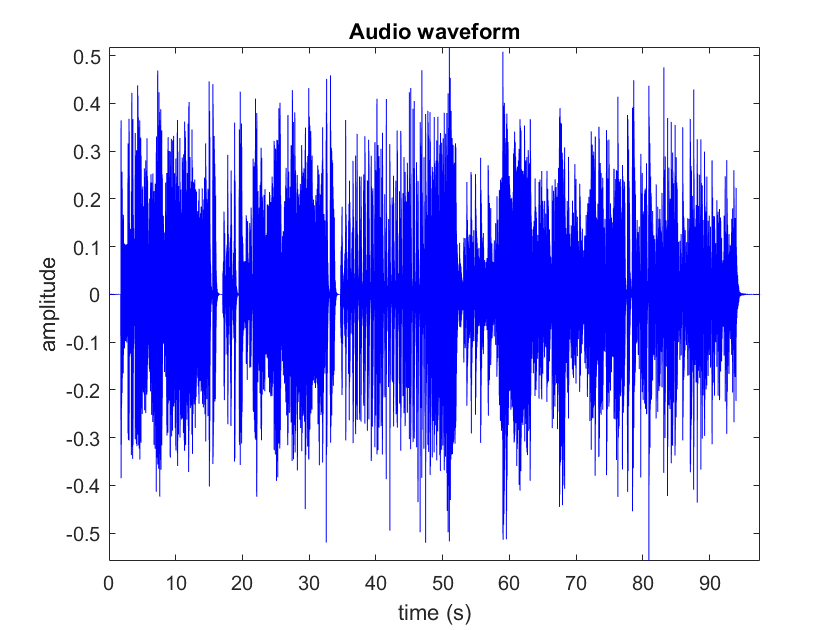

Its content is displayed in Figure 1.
 


% plotting the soundwave
miraudio(our_audio_data)

Computing mirspectrum related to pianist.wav...
 
ans is the Spectrum related to pianist.wav, of sampling rate 44100 Hz.


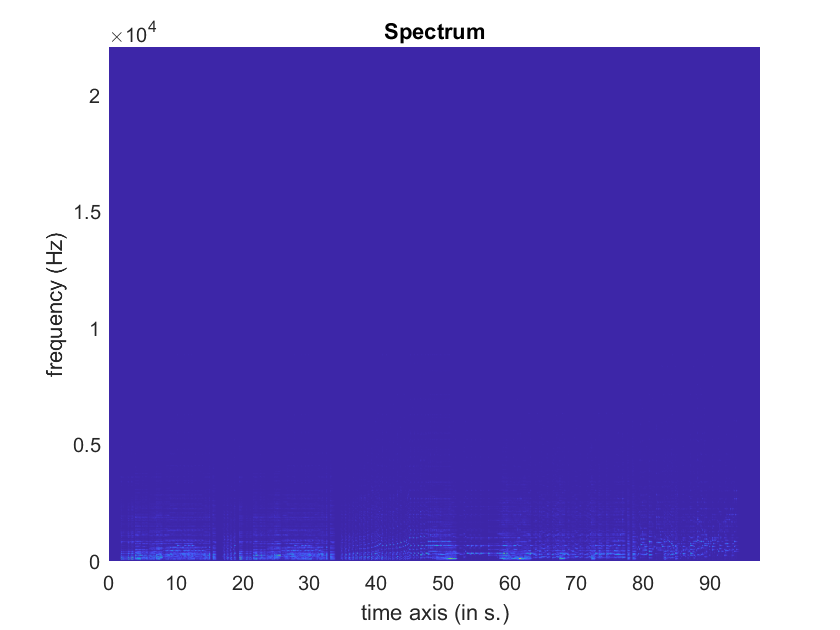

Its content is displayed in Figure 2.
 


% plotting the spectrogram
mirspectrum(our_audio_data, 'Frame')

Computing mirspectrum related to pianist.wav...
Computing mirmfcc related to pianist.wav...
 
ans is the MFCC related to pianist.wav, of sampling rate 44100 Hz.


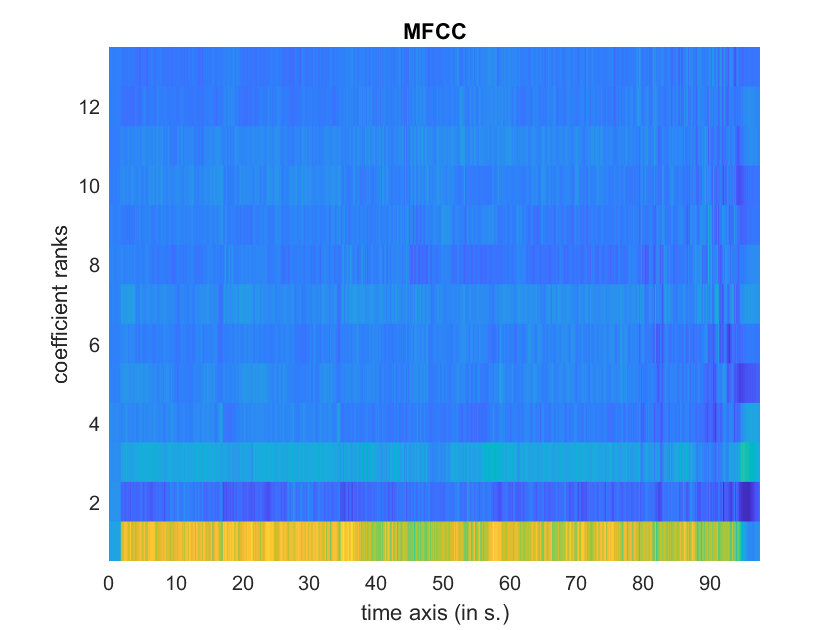

Its content is displayed in Figure 3.
 


% plotting the mel-spectrogram
mirmfcc(our_audio_data, 'Frame')

We will use an example file from MG Toolbox. Before we proceed to the analysis and visualization of this sound file, we can use MIR Toolbox to hear it! 

mirplay(our_audio_data)

Computing mirplay related to pianist.wav...
Playing file: pianist.wav

ans =

  0×0 empty cell array



# Feature Extraction and Visualization 

Now, let's start analyzing our audio!

## Dynamics 

mirrms(our_audio_data) % root mean square of average perceived loudness

Computing mirrms related to pianist.wav...
 
The RMS energy related to file pianist.wav is 0.076282 
 


mirrms(our_audio_data, 'Frame') 

Computing mirrms related to pianist.wav...
 
The RMS energy related to file pianist.wav is displayed in Figure 4.
 


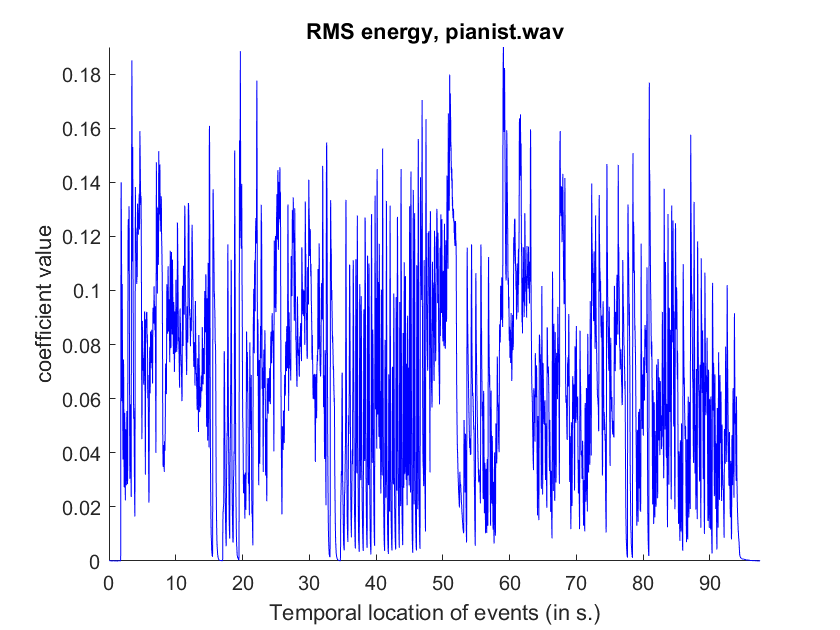


xlim([0.0 97.5])
ylim([0.000 0.190])
zlim([0.000 1.000])

mirlowenergy(our_audio_data, 'Frame') %  percentage of frames showing less-than-average energy

Computing mirrms related to pianist.wav...
Computing mirlowenergy related to pianist.wav...
 
The Low energy related to file pianist.wav is 0.49962 
 


## Rhythm

mirtempo(our_audio_data) % tempo in BPM

Computing mirfilterbank related to pianist.wav...
Computing mirenvelope related to pianist.wav...
Computing mironsets related to pianist.wav...
Computing mirenvelope related to pianist.wav...
Computing mirenvelope related to pianist.wav...
Computing mirsum related to pianist.wav...
Computing mirenvelope related to pianist.wav...
Computing mirautocor related to pianist.wav...
Computing mirpeaks related to pianist.wav...
Computing mirpeaks related to pianist.wav...
Computing mirsum related to pianist.wav...
Computing mirpeaks related to pianist.wav...
Computing mirtempo related to pianist.wav...
 
The Tempo related to file pianist.wav is 109.9682 bpm
 


mirpulseclarity(our_audio_data) % pulse clarity estimation 

Computing mirspectrum related to pianist.wav...
Computing mirenvelope related to pianist.wav...
Computing mironsets related to pianist.wav...
Computing mirenvelope related to pianist.wav...
Computing mirsum related to pianist.wav...
Computing mirenvelope related to pianist.wav...
Computing mirautocor related to pianist.wav...
Computing mirsum related to pianist.wav...
Computing mirpeaks related to pianist.wav...
Computing mirtempo related to pianist.wav...
Computing mirpulseclarity related to pianist.wav...
 
The Pulse clarity related to file pianist.wav is 0.21759 
 


## Timbre

Computing mirspectrum related to pianist.wav...
Computing mirenvelope related to pianist.wav...
Computing mironsets related to pianist.wav...
Computing mirsum related to pianist.wav...
Computing mirenvelope related to pianist.wav...
Computing mirpeaks related to pianist.wav...
 
event is the Onset curve (Envelope) related to pianist.wav, of sampling rate 100 Hz.


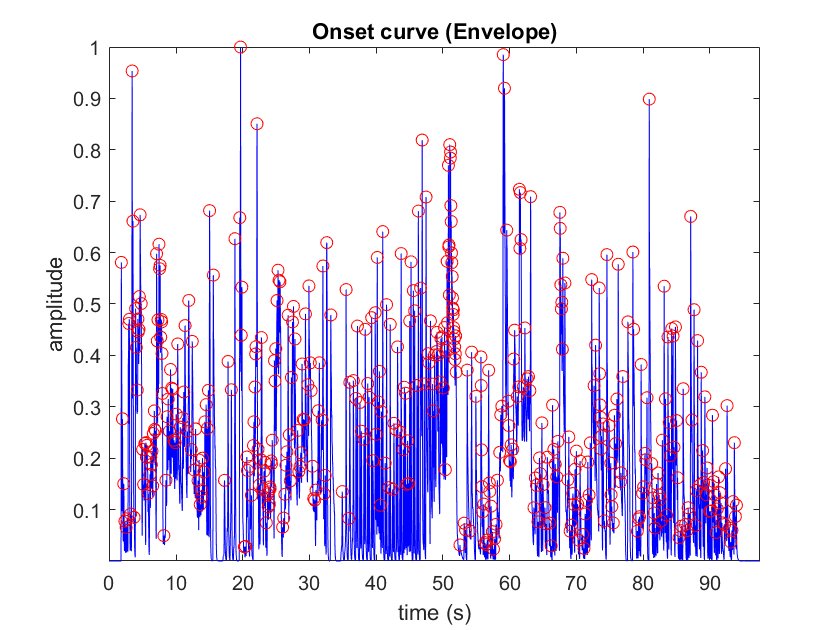

Its content is displayed in Figure 5.
 


event = mirevents(our_audio_data) % onset curve computation

mirattacktime(event) % estimating attack time

Computing mironsets related to pianist.wav...
Computing mirsum related to pianist.wav...
Computing mironsets related to pianist.wav...
Computing mirenvelope related to pianist.wav...
Computing mirsum related to pianist.wav...
Computing mirenvelope related to pianist.wav...
Computing mirpeaks related to pianist.wav...
Computing mirpeaks related to pianist.wav...
Computing mirattacktime related to pianist.wav...
 
The Attack Time related to file pianist.wav is displayed in Figure 6.
 


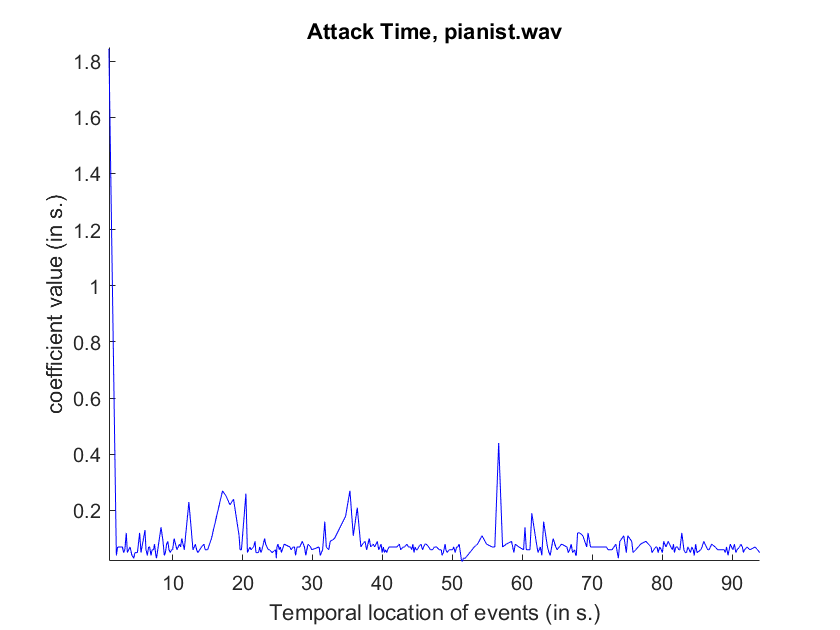

xlim([0.832 0.999])
ylim([1.6223 1.6775])
zlim([0.000 1.000])
ax = gca;
chart = ax.Children(1);
datatip(chart,0.885,1.85);

xlim([0.879 1.046])
ylim([1.6326 1.6878])
zlim([0.000 1.000])

xlim([0.9 94.0])
ylim([0.02 1.85])
zlim([0.000 1.000])

mirroughness(our_audio_data, 'Frame') % amount of sensory dissonance

Computing mirspectrum related to pianist.wav...
Computing mirpeaks related to pianist.wav...
Computing mirroughness related to pianist.wav...
 
The Roughness (Sethares) related to file pianist.wav is displayed in Figure 7.
 


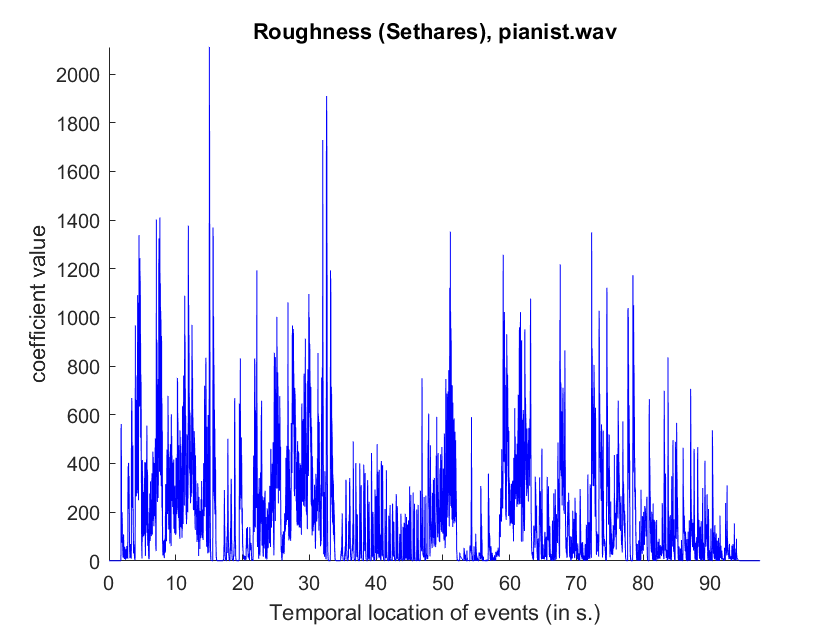

xlim([0.0 97.5])
ylim([-1 2111])
zlim([0.000 1.000])

mirbrightness(our_audio_data) % measuring the amount of energy above the cut-off frequency

Computing mirspectrum related to pianist.wav...
Computing mirbrightness related to pianist.wav...
Computing mirrms related to pianist.wav...
 
The Brightness related to file pianist.wav is 0.2545 
 


It is useful to compare with another sound:

mirplay('czardas.wav')

Computing miraudio related to czardas.wav...
Computing mirsum related to czardas.wav...
Computing mirspectrum related to czardas.wav...
Computing mirenvelope related to czardas.wav...
Computing mironsets related to czardas.wav...
Computing mirsum related to czardas.wav...
Computing mirenvelope related to czardas.wav...
Computing mirpeaks related to czardas.wav...
Elapsed time is 1.815068 seconds.
 
events is the Onset curve (Envelope) related to czardas.wav, of sampling rate 100.2273 Hz.


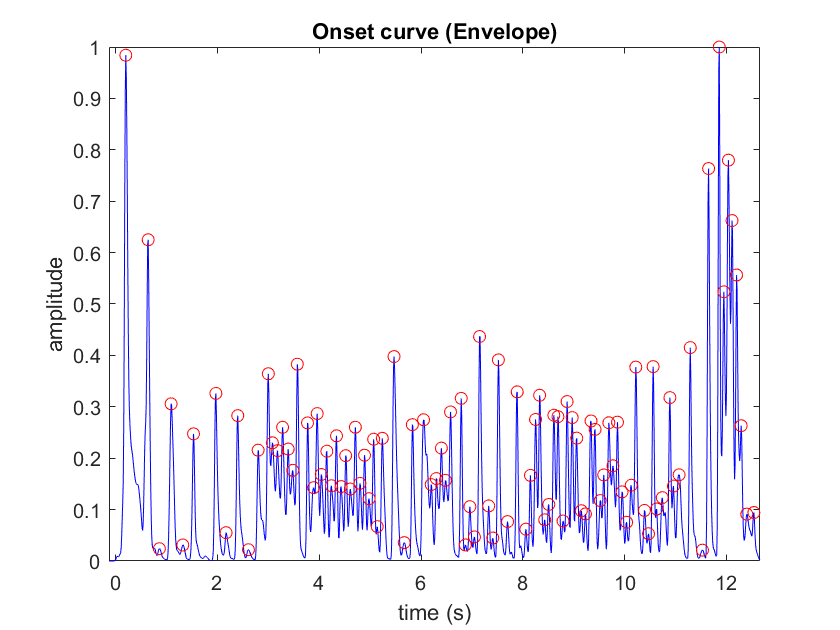

Its content is displayed in Figure 8.
 


events = mirevents('czardas.wav')

Computing mironsets related to czardas.wav...
Computing mirsum related to czardas.wav...
Computing mironsets related to czardas.wav...
Computing mirenvelope related to czardas.wav...
Computing mirsum related to czardas.wav...
Computing mirenvelope related to czardas.wav...
Computing mirpeaks related to czardas.wav...
Computing mirpeaks related to czardas.wav...
Computing mirattacktime related to czardas.wav...
 
The Attack Time related to file czardas.wav is displayed in Figure 9.


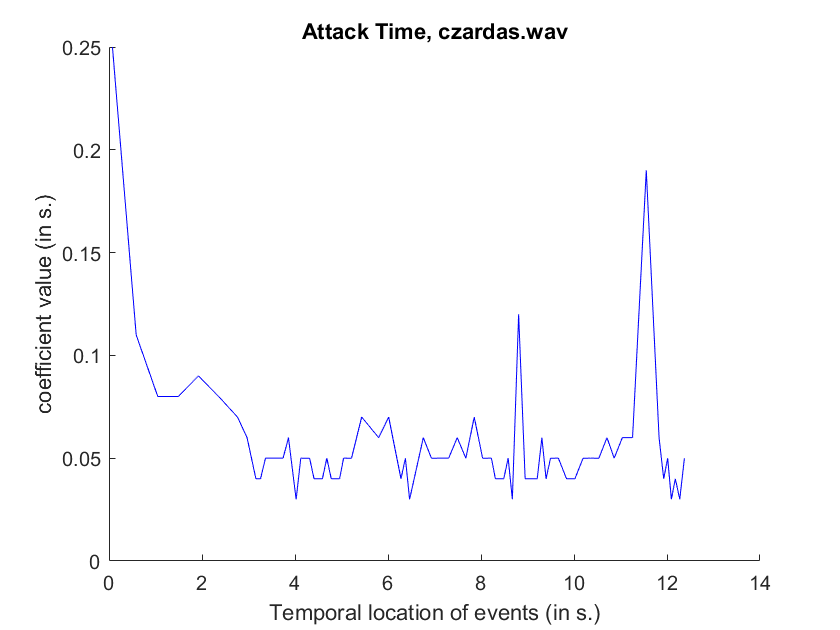

 
 
events is the Onset curve (Envelope) related to czardas.wav, of sampling rate 100.2273 Hz.
Its content is displayed in Figure 10.
 


[attacktime, events] = mirattacktime(events)% we can show attack time and envelope at the same example

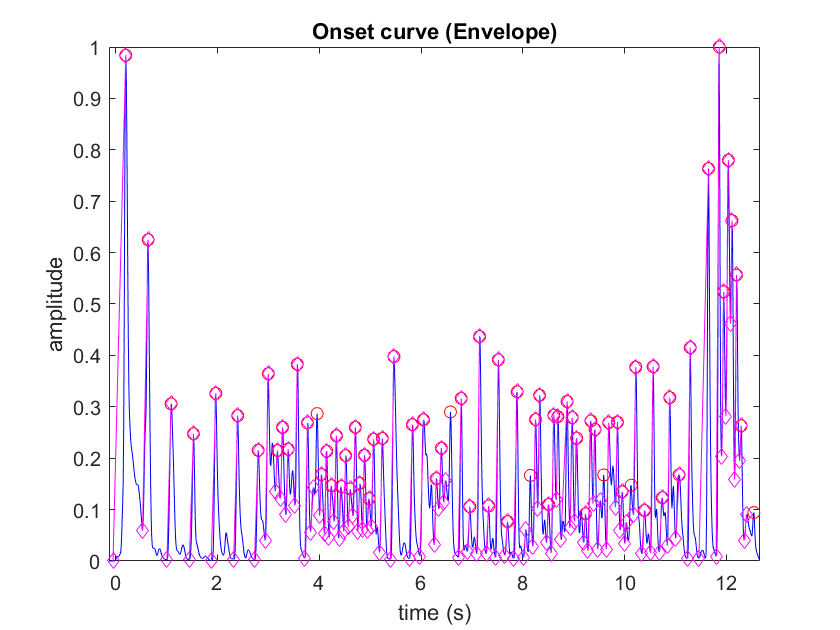


xlim([0.00 12.37])
ylim([0.030 0.260])
zlim([0.000 1.000])

xlim([0.00 12.37])
ylim([0.030 0.260])
zlim([0.000 1.000])
xlim([0.00 12.37])
ylim([0.030 0.260])
zlim([0.000 1.000])

xlim([0.00 12.37])
ylim([0.030 0.260])
zlim([0.000 1.000])

xlim([-0.13 12.66])
ylim([0.000 1.000])
zlim([0.000 1.000])

## Tonality 

Analyzing the tonality of musical audio from a technical perspective involves quantifying and understanding the harmonic and melodic aspects that define the key and tonal center of a piece of music. 

Computing mirspectrum related to pianist.wav...
Computing mirchromagram related to pianist.wav...
Computing mirkeystrength related to pianist.wav...
 
ans is the Key strength related to pianist.wav, of sampling rate 44100 Hz.


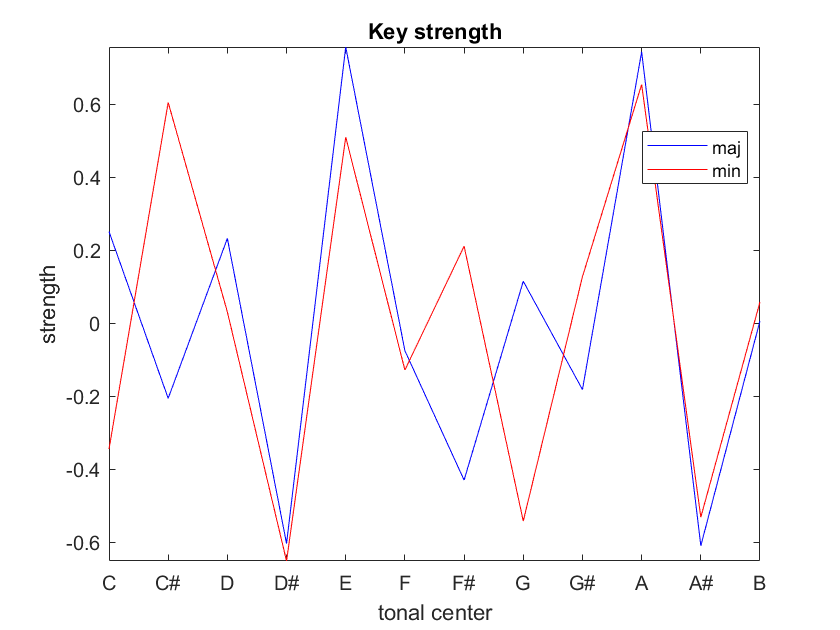

Its content is displayed in Figure 11.
 


mirkeystrength(our_audio_data) % indicates the correlation coefficient for each different tonality candidate

mirkey(our_audio_data) %  estimation of tonal center positions and their respective clarity

Computing mirspectrum related to pianist.wav...
Computing mirchromagram related to pianist.wav...
Computing mirkeystrength related to pianist.wav...
Computing mirpeaks related to pianist.wav...
Computing mirkey related to pianist.wav...
 
The Key related to file pianist.wav is E maj
 


Computing miraudio related to Cmaj.wav...
Computing mirsum related to Cmaj.wav...
Computing mirspectrum related to Cmaj.wav...
Computing mirchromagram related to Cmaj.wav...
Computing mirkeystrength related to Cmaj.wav...
Elapsed time is 1.195464 seconds.
 
ans is the Key strength related to Cmaj.wav, of sampling rate 44100 Hz.


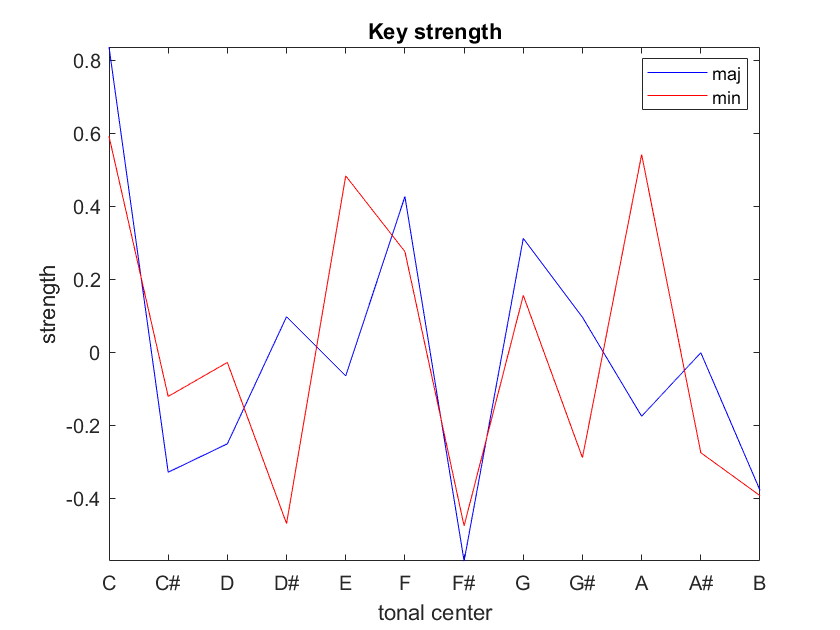

Its content is displayed in Figure 12.
 


mirkeystrength('Cmaj.wav')

mirkey('Cmaj.wav')

Computing miraudio related to Cmaj.wav...
Computing mirsum related to Cmaj.wav...
Computing mirspectrum related to Cmaj.wav...
Computing mirchromagram related to Cmaj.wav...
Computing mirkeystrength related to Cmaj.wav...
Computing mirpeaks related to Cmaj.wav...
Computing mirkey related to Cmaj.wav...
Elapsed time is 0.689635 seconds.
 
The Key related to file Cmaj.wav is C maj
 


Computing miraudio related to pianogminor.wav...
Computing mirsum related to pianogminor.wav...
Computing mirspectrum related to pianogminor.wav...
Computing mirchromagram related to pianogminor.wav...
Computing mirkeystrength related to pianogminor.wav...
Elapsed time is 1.630317 seconds.
 
ans is the Key strength related to pianogminor.wav, of sampling rate 44100 Hz.


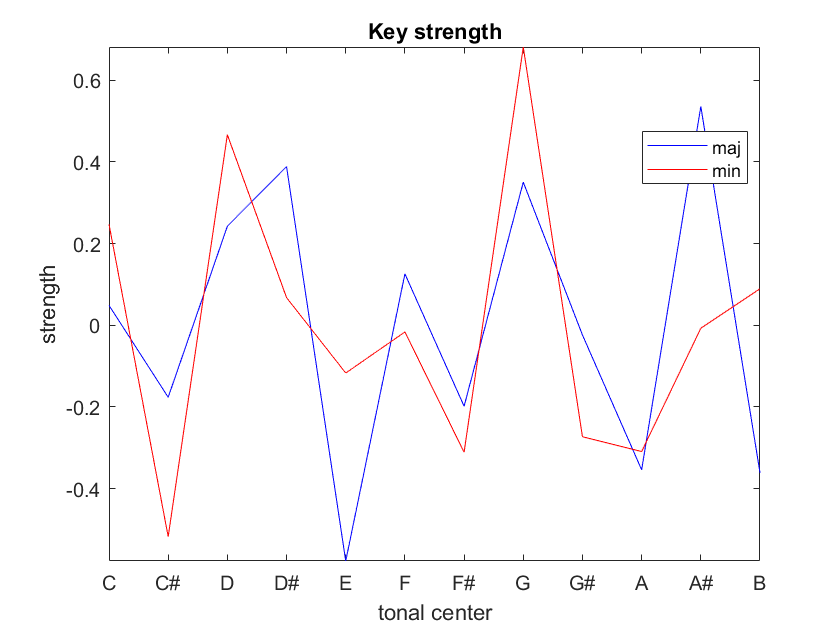

Its content is displayed in Figure 13.
 


mirkeystrength('pianogminor.wav')

mirkey('pianogminor.wav')

Computing miraudio related to pianogminor.wav...
Computing mirsum related to pianogminor.wav...
Computing mirspectrum related to pianogminor.wav...
Computing mirchromagram related to pianogminor.wav...
Computing mirkeystrength related to pianogminor.wav...
Computing mirpeaks related to pianogminor.wav...
Computing mirkey related to pianogminor.wav...
Elapsed time is 1.387497 seconds.
 
The Key related to file pianogminor.wav is G min
 


# VIDEO 

This part of the script allows us to explore feature extraction and visualization from video data, using the MG Toolbox and other built-in MATLAB functions.

our_video_data = VideoReader('pianist.avi') % Reading the video file

our_video_data =   VideoReader with properties:

   General Properties:
            Name: 'pianist.avi'
            Path: 'C:\Users\user\Downloads\MGT-matlab-master\examples\pianist'
        Duration: 97.5000
     CurrentTime: 0
       NumFrames: 2925

   Video Properties:
           Width: 640
          Height: 480
       FrameRate: 30
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


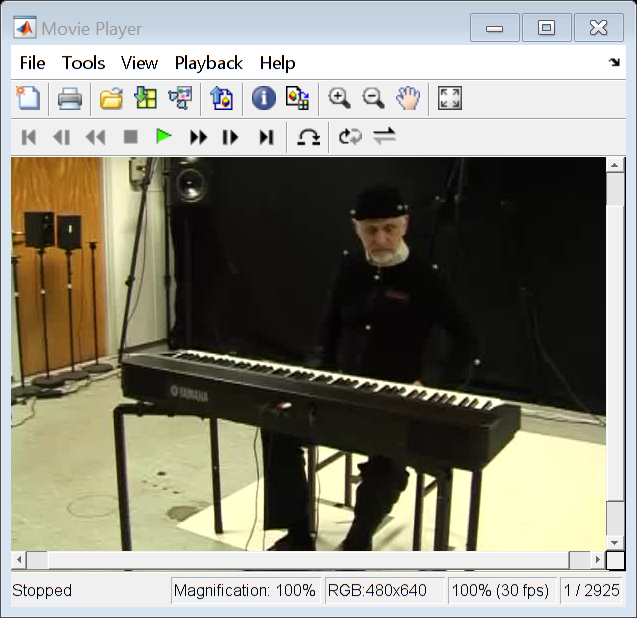

implay('pianist.avi') % plays our video 

## Video Processing

mgvideocrop(our_video_data,[20 30 30 20],'newfilename.avi') % cropping. filename, 2 by N position, new filename
mgvideorotate(our_video_data, 90, 'bilinear') % rotating. filename, angle, method
mgvideoadjust(our_video_data,[0.1;0.8],[0.2;0.9]) % adjusting. filename, mapin, mapout

## Motion Analysis 

mgmotionaverage('pianist.avi'); % average image of our video

cmd = struct with fields:
               mg: []
           method: 'Diff'
         fileList: []
       filterflag: 0
       filtertype: []
           thresh: 0.1000
            color: 'off'
           invert: 'off'
    frameInterval: 1
        fileCount: 0
        normalize: 'on'


input is file or folder
folder does not exist. probably the input is file
file exists. checking file format
valid file format
 
process in progress :99%

aveOut =            0           0           0           0           0           0           0           0           0           0           0           0           0           0           0        2900        6357        8096        2362       14286      192684      207820      197292      200113      179814      193771      204141      195186      178744      173238      187491      204894      198328      195864      188472      183544      183544      188472      195864      198328      187592      193297      201959      204953      205064      202098      193259      187264      208749      191476
           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0        2515        6357        8038        2328       14289      192684      207845      197292      200113      181421      194769      203491      197252      179492      176263      189484      206323      

 
file created under name :
pianist_average.tiff


## Visualization

% Initializing the structs
mg = mgread('pianist.avi', 'pianist.wav', 'pianist.tsv');

.avi
.wav
Computing miraudio related to pianist.wav...
Computing mirsum related to pianist.wav...
Elapsed time is 1.511142 seconds.
.tsv


mgseg = mgreadsegment(mg,10,30);

Computing miraudio related to pianist.wav...
****reading temporal segment**100% 


the trimmed video is created with name pianist_segment.avi


mgsegmo = mgmotion(mgseg,'Diff ');

input is mg struct
 
 
process in progress :11100% 

 
The motion video is created with name pianist_segment_motion.avi


mgsegop = mgmotion(mgseg,'OpticalFlow');

input is mg struct
method specified in argument
input type accepts starttime and stoptime only if input is file or struct and not folder
 
process in progress :  
 0% 1% 1% 1% 1% 1% 1% 2% 2% 2% 2% 2% 2% 3% 3% 3% 3% 3% 3% 4% 4% 4% 4% 4% 4% 5% 5% 5% 5% 5% 5% 6% 6% 6% 6% 6% 6% 7% 7% 7% 7% 7% 7% 8% 8% 8% 8% 8% 8% 9% 9% 9% 9% 9% 9%10%10%10%10%10%10%11%11%11%11%11%11%11%12%12%12%12%12%13%13%13%13%13%13%14%14%14%14%14%14%15%15%15%15%15%15%16%16%16%16%16%16%17%17%17%17%17%17%18%18%18%18%18%18%19%19%19%19%19%19%20%20%20%20%20%20%20%21%21%21%21%21%22%22%22%22%22%22%23%23%23%23%23%23%24%24%24%24%24%24%25%25%25%25%25%25%25%26%26%26%26%26%27%27%27%27%27%27%28%28%28%28%28%28%29%29%29%29%29%29%30%30%30%30%30%30%31%31%31%31%31%31%32%32%32%32%32%32%33%33%33%33%33%33%34%34%34%34%34%34%35%35%35%35%35%35%36%36%36%36%36%36%37%37%37%37%37%37%38%38%38%38%38%38%39%39%39%39%39%39%40%40%40%40%40%40%41%41%41%41%41%41%42%42%42%42%42%42%43%43%43%43%43%43%43%44%44%44%44%44%45%45%45%45%45%45%46%46%46%46%46%46%47%47%

# MOTION CAPTURE

This part of the script allows us to explore feature extraction and visualization from motion capture data, using the MoCap Toolbox.

## Motion Capture Data Processing

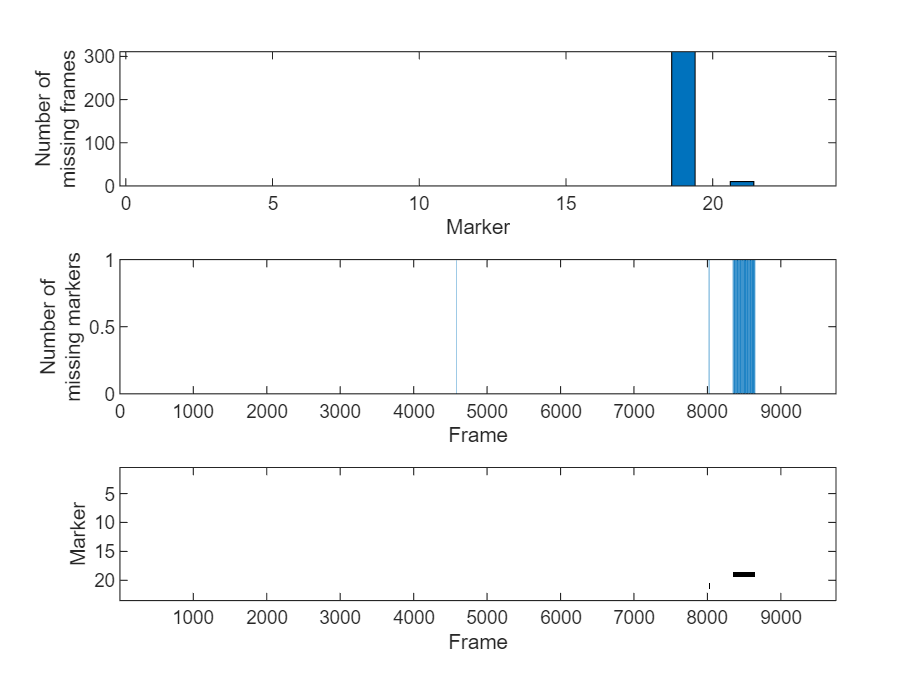

[mf, mm, mgrid] = mcmissing(our_mocap_data, plot=true); % checking for missing markers

mcfillgaps(our_mocap_data) % filling the gaps in our data

ans = struct with fields:
            type: 'MoCap data'
        filename: 'pianist.tsv'
         nFrames: 9750
        nCameras: 9
        nMarkers: 23
            freq: 100
         nAnalog: 0
         anaFreq: 0
    timederOrder: 0
      markerName: {23×1 cell}
            data: [9750×69 double]
      analogdata: []
           other: [1×1 struct]


## Visualization

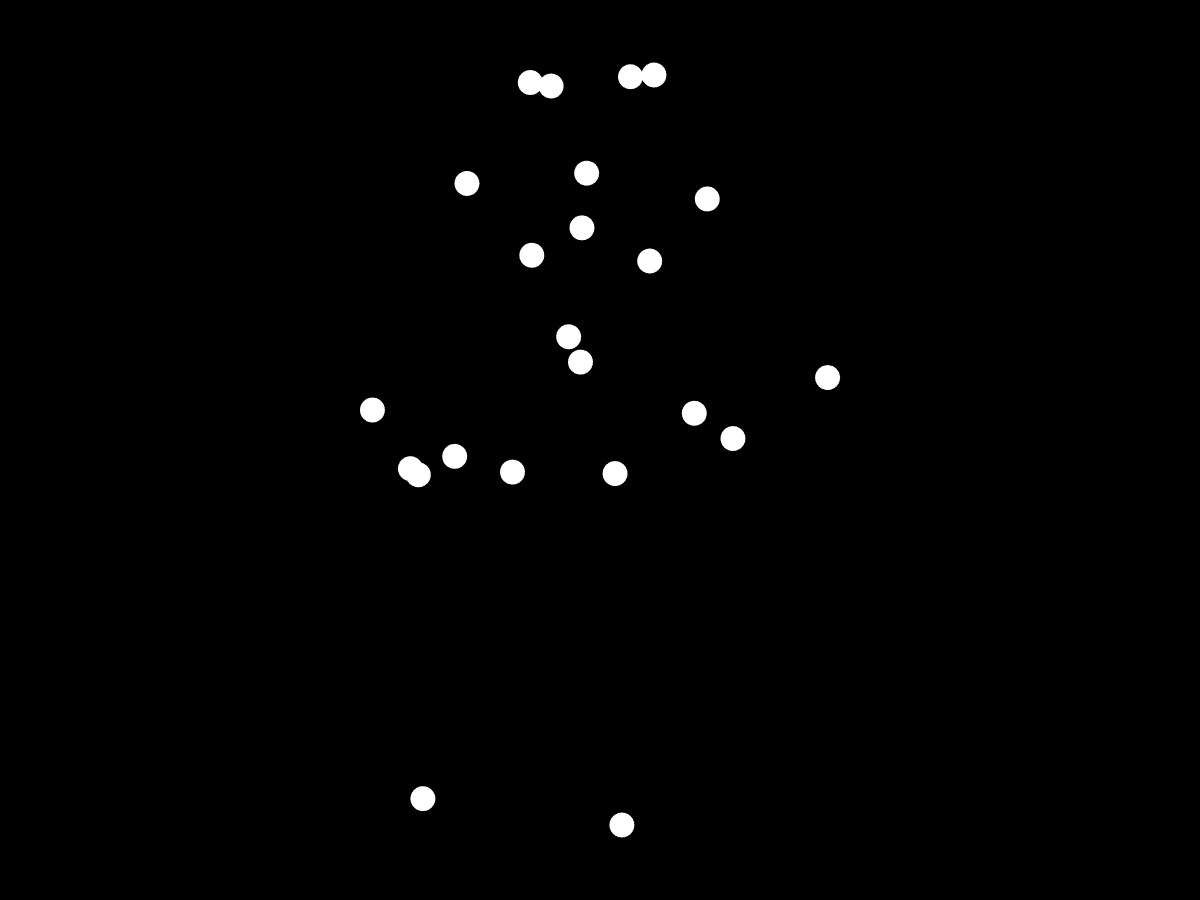

ans = struct with fields:
            type: 'animpar'
         scrsize: [800 600]
          limits: []
              az: 0
              el: 0
           msize: 12
          colors: [5×3 double]
    markercolors: [23×3 double]
      conncolors: [0×3 double]
     tracecolors: []
    numbercolors: []
          cwidth: 1
          twidth: 1
            conn: []
           conn2: []
             trm: []
             trl: 0
        showmnum: 0
         numbers: []
        showfnum: 0
      background: [1×1 struct]
         animate: 0
         visible: 1
            hold: 0
             fps: 30
          output: 'tmp'
     videoformat: 'avi'
    createframes: 0
       getparams: 0
     perspective: 0
            pers: [1×1 struct]


mcplotframe(our_mocap_data, 1) % frame visualization

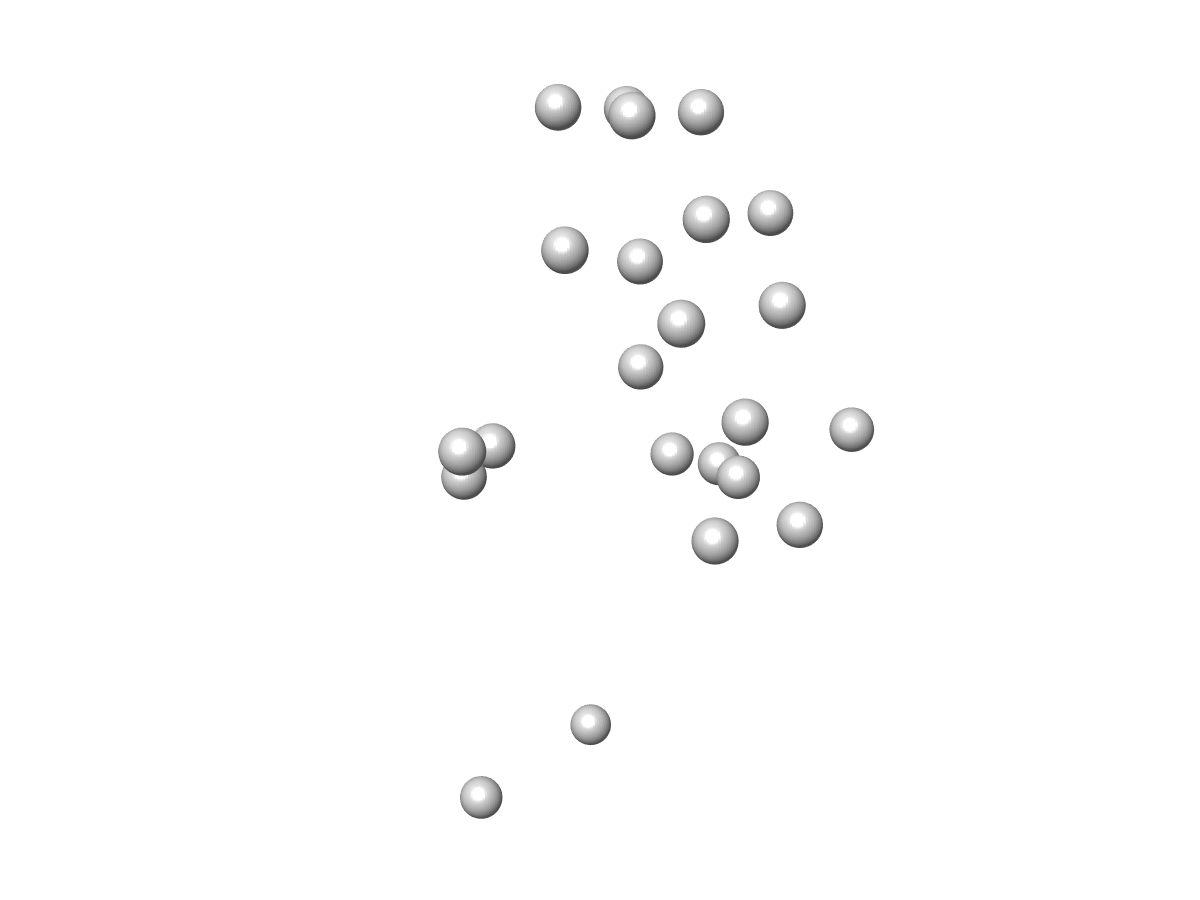

ans = struct with fields:
            type: 'animpar'
         scrsize: [800 600]
          limits: []
              az: 50
              el: 10
           msize: 12
          colors: [5×3 double]
    markercolors: [23×3 double]
      conncolors: [0×3 double]
     tracecolors: []
    numbercolors: []
          cwidth: 1
          twidth: 1
            conn: []
           conn2: []
             trm: []
             trl: 0
        showmnum: 0
         numbers: []
        showfnum: 0
      background: [1×1 struct]
         animate: 0
         visible: 1
            hold: 0
             fps: 30
          output: 'tmp'
     videoformat: 'avi'
    createframes: 0
       getparams: 0
     perspective: 0
            pers: [1×1 struct]
           par3D: [1×1 struct]


mcplot3Dframe(our_mocap_data, 1) % three-dimensional visualization

par = mcanimate(our_mocap_data);

ans = struct with fields:
            type: 'MoCap data'
        filename: 'pianist.tsv'
         nFrames: 9750
        nCameras: 9
        nMarkers: 23
            freq: 100
         nAnalog: 0
         anaFreq: 0
    timederOrder: 0
      markerName: {23×1 cell}
            data: [9750×69 double]
      analogdata: []
           other: [1×1 struct]


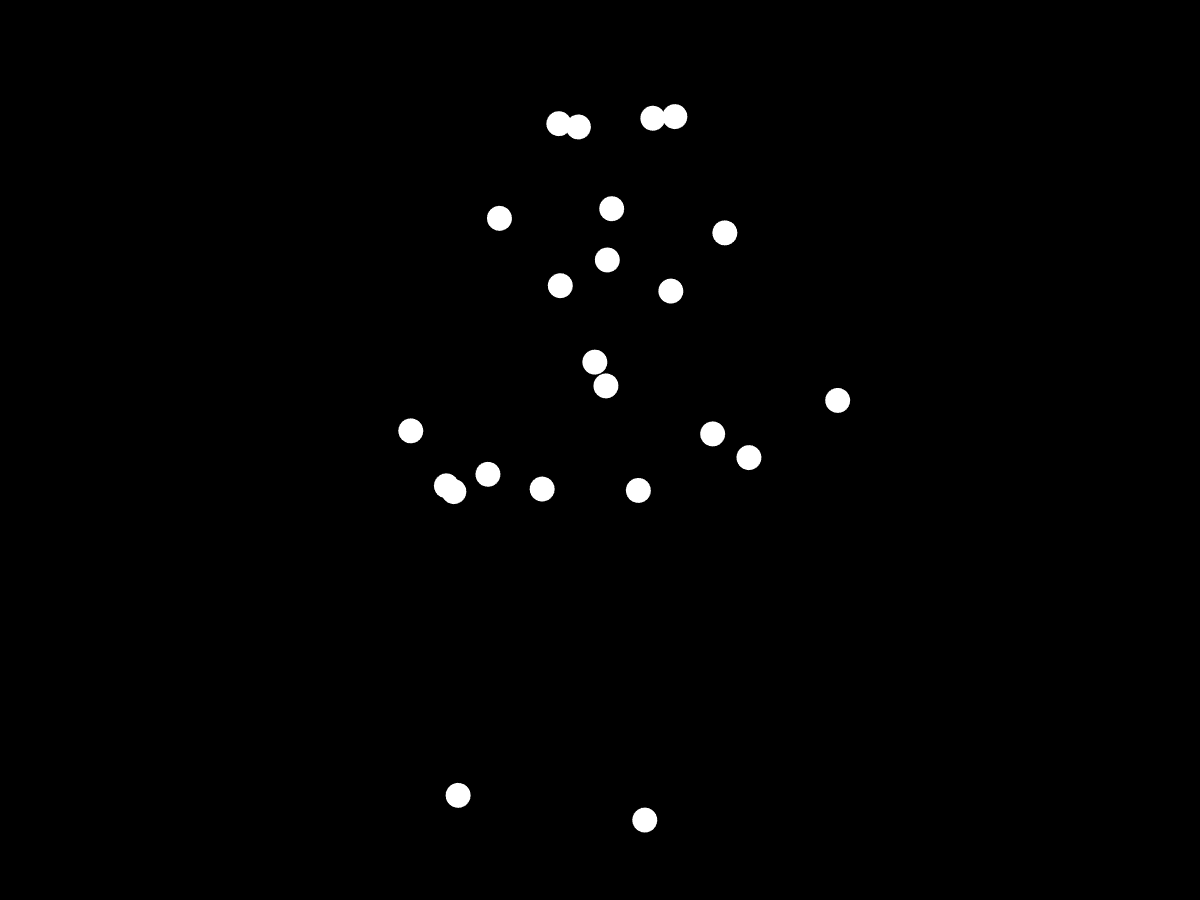

par = mcanimate(our_mocap_data, par);

## Kinematic Analysis

Kinematic analysis in the context of multimodal music analysis involves the study of the motion and physical movements of musicians, dancers, or performers during a musical performance. It is a valuable tool for gaining insights into the expressive and technical aspects of a performance. 

mccumdist(our_mocap_data) % cumulative distance computation

ans = struct with fields:
            type: 'norm data'
        filename: 'pianist.tsv'
         nFrames: 9750
        nCameras: 9
        nMarkers: 23
            freq: 100
         nAnalog: 0
         anaFreq: 0
    timederOrder: 0
      markerName: {23×1 cell}
            data: [9750×23 double]
      analogdata: []
           other: [1×1 struct]


mcfluidity(our_mocap_data) % fluidity of motion 

ans = 0.0474

[per, ac, eac, lag] = mcperiod(our_mocap_data) % period of movement

per =        NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    1.1374       NaN       NaN       NaN       NaN       NaN       NaN    1.7293       NaN       NaN    0.5431       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN


ac = 	1.0e+08 *

    0.5455    0.2853    0.0710    0.5547    0.3594    0.0250    0.5485    0.2528    0.2785    0.5244    0.3327    0.1706    0.4935    0.0650    0.0534    0.7163    0.3187       NaN    0.5232    0.0788    0.0114    0.8198    0.3932    0.0436    1.4857    0.3560    0.1983    0.4893    0.0811    0.0036    0.1960    0.0230    0.0050    0.4595    0.0501    0.0390    0.3011    0.0306    0.0123    0.0299    0.0055    0.0106    0.0333    0.0080    0.0058    0.3607    0.0420    0.0157    0.3506    0.0425
    0.5454    0.2852    0.0709    0.5546    0.3594    0.0250    0.5484    0.2527    0.2784    0.5244    0.3327    0.1705    0.4934    0.0650    0.0534    0.7162    0.3185       NaN    0.5231    0.0788    0.0113    0.8196    0.3929    0.0435    1.4853    0.3557    0.1977    0.4892    0.0811    0.0036    0.1960    0.0229    0.0050    0.4594    0.0501    0.0389    0.3011    0.0306    0.0122    0.0298    0.0055    0.0106    0.0333    0.0080    0.0058    0.3606    0.0420    0.0157  

eac =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

lag =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900
